# Atividade 02 - Série Trigonométrica de Fourier

## Boas práticas

clear;                  %%% limpando todas as variáveis
close all;              %%% fechando todas as figuras
clc;                    %%% limpando a tela

## Exercício 1

### Definição das Variaveis 

syms T0 w0 Ap An t1 t2 t3 n t    %%% Variáveis simbólicas

#### Definindo de forma generica o termo: an

an_generico = 2*int(Ap*cos(n*w0*t), t, t1, t2)/T0 + 2*int(An*cos(n*w0*t), t, t2, t3)/T0    %%% Forma generica do an (somando os períodos)

$$an\_generico = -\frac{2\,\mathrm{An}\,\left(\sin\left(n\,t_{2}\,w_{0}\right)-\sin\left(n\,t_{3}\,w_{0}\right)\right)}{T_{0}\,n\,w_{0}}-\frac{2\,\mathrm{Ap}\,\left(\sin\left(n\,t_{1}\,w_{0}\right)-\sin\left(n\,t_{2}\,w_{0}\right)\right)}{T_{0}\,n\,w_{0}}$$

#### Definindo de forma generica o termo: bn

bn_generico = 2*int(Ap*sin(n*w0*t), t, t1, t2)/T0 + 2*int(An*sin(n*w0*t), t, t2, t3)/T0     %%% Forma generica do bn (somando os períodos)

$$bn\_generico = \frac{2\,\mathrm{An}\,\left(\cos\left(n\,t_{2}\,w_{0}\right)-\cos\left(n\,t_{3}\,w_{0}\right)\right)}{T_{0}\,n\,w_{0}}+\frac{2\,\mathrm{Ap}\,\left(\cos\left(n\,t_{1}\,w_{0}\right)-\cos\left(n\,t_{2}\,w_{0}\right)\right)}{T_{0}\,n\,w_{0}}$$

#### Definindo de forma generica o termo: a0

a0_generico = 1*int(Ap,t, t1, t2)/T0 + 1*int(An, t, t2, t3)/T0                           %%% Forma generica do a0 (somando os períodos)

$$a0\_generico = -\frac{\mathrm{An}\,\left(t_{2}-t_{3}\right)}{T_{0}}-\frac{\mathrm{Ap}\,\left(t_{1}-t_{2}\right)}{T_{0}}$$

### Definindo as variaveis de forma numerica

%%% T0  -> Período da função g(t)
%%% w0  -> Frequência angular fundamental (w0 = 2*pi/T0)

T0 = 4;                     %%% Periodo
w0 = 2*pi/T0;               %%% Frequencia Angular

#### Defindo de forma numerica o termo: an

an = 2*int(0*cos(n*w0*t), t, -2, -1/2)/T0 + 2*int(1*cos(n*w0*t), t, -1/2, 1/2)/T0 + + 2*int(0*cos(n*w0*t), t, 1/2, 2)/T0    %%% Forma numerica (somando os períodos)

$$an = \frac{2\,\sin\left(\frac{\pi \,n}{4}\right)}{n\,\pi }$$

#### Defindo de forma numerica o termo: bn

bn = 2*int(0*sin(n*w0*t), t, -2, -1/2)/T0 + 2*int(1*sin(n*w0*t), t, -1/2, 1/2)/T0 + + 2*int(0*sin(n*w0*t), t, 1/2, 2)/T0    %%% Forma numerica (somando os períodos)

$$bn = 0$$

#### Defindo de forma numerica o term: a0

a0 = 1*int(0,t, -2, -1/2)/T0 + 1*int(1, t, -1/2, 1/2)/T0 + 1*int(0, t, 1/2, 2)/T0                                           %%% Forma numerica (somando os períodos)

$$a0 = \frac{1}{4}$$

## Exercício 2

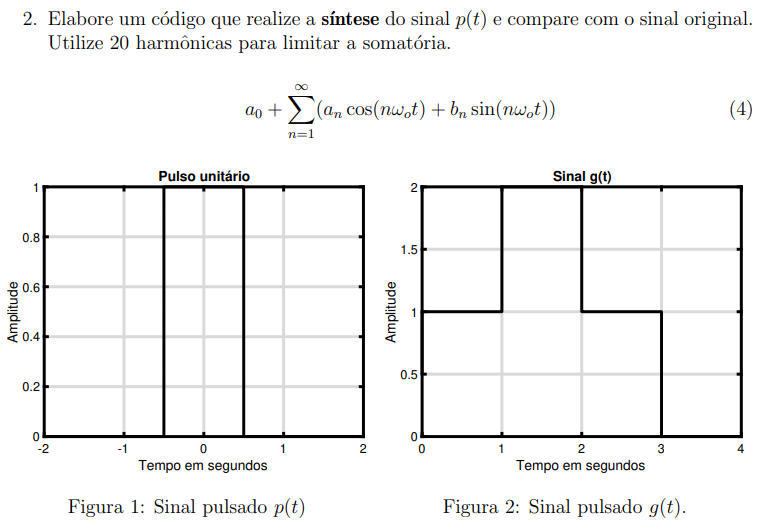

### Definindo intervalos

%%% N       -> Número do harmônico considerado
%%% n       -> Distribuição das harmônicas
%%% tempo   -> Intervalo de tempo

N = 20;                     %%% Numero de harmônicas
n = 1:1:N;                  %%% Definicao de como exibir as n harmonicas
aux = a0;                   %%% Valor inicial da somatoria (valor medio da função no periodo)
tempo = -2:1e-3:2;          %%% Intervalo de tempo

### Atribuição dos valores

a_n = eval(an);              %%% Valor numerico de an
b_n0 = eval(bn)              %%% Valor numérico de bn

b_n0 = 0

b_n = zeros(1, N)          %%% bn = 0, portanto, foi criado um vetor cujos elementos sao nulos, para realizacao da somatoria

b_n =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


### Somatória das Harmônicas na Série

for k=1:N
    aux =  aux + a_n(k)*cos(n(k)*w0*tempo)+b_n(k)*sin(n(k)*w0*tempo);
end

### Plotagem do gráfico

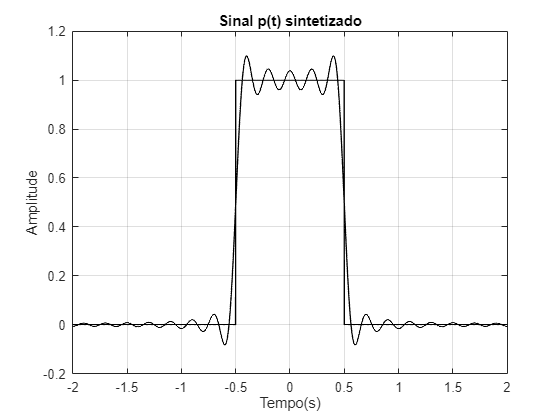

plot(tempo, aux,'LineWidth',1,'Color','k'); hold on;       %%% Gráfico do sinal sintetizado
plot(tempo,rectpuls(tempo), 'LineWidth',1,'Color','k')     %%% Gráfico do sinal pulsado
hold off;                                                  %%% Parar de salvar o plot               

title('Sinal p(t) sintetizado')                            %%% Título do gráfico
xlabel('Tempo(s)')                                         %%% Título do eixo x
ylabel('Amplitude')                                        %%% Título do eixo y
grid;                                                      %%% Exibição com quadriculado

## Exercício 3

### Definição dos Valores

T0 = 4;                 %%% Período 
w0 = 2*pi/T0;           %%% Frequência angular 

## Coeficientes an, bn e a0 da série para g(t) 

an = (2/T0)*(int(1*cos(n*w0*t), t, 0, 1)+int(2*cos(n*w0*t), t, 1, 2)+int(1*cos(n*w0*t), t, 2, 3))   %%% Termo an (somando os períodos)

$$an = \left(\begin{array}{cccccccccccccccccccc} -\frac{2}{\pi } & 0 & \frac{2}{3\,\pi } & 0 & -\frac{2}{5\,\pi } & 0 & \frac{2}{7\,\pi } & 0 & -\frac{2}{9\,\pi } & 0 & \frac{2}{11\,\pi } & 0 & -\frac{2}{13\,\pi } & 0 & \frac{2}{15\,\pi } & 0 & -\frac{2}{17\,\pi } & 0 & \frac{2}{19\,\pi } & 0 \end{array}\right)$$

bn = (2/T0)*(int(1*sin(n*w0*t), t, 0, 1)+int(2*sin(n*w0*t), t, 1, 2)+int(1*sin(n*w0*t), t, 2, 3))   %%% Termo bn (somando os períodos)

$$bn = \left(\begin{array}{cccccccccccccccccccc} \frac{2}{\pi } & 0 & \frac{2}{3\,\pi } & 0 & \frac{2}{5\,\pi } & 0 & \frac{2}{7\,\pi } & 0 & \frac{2}{9\,\pi } & 0 & \frac{2}{11\,\pi } & 0 & \frac{2}{13\,\pi } & 0 & \frac{2}{15\,\pi } & 0 & \frac{2}{17\,\pi } & 0 & \frac{2}{19\,\pi } & 0 \end{array}\right)$$

a0 = (1/T0)*(int(1, t, 0, 1)+int(2, t, 1, 2)+int(1, t, 2, 3))                                       %%% Termo a0 (somando os períodos)

$$a0 = 1$$

## Exercício 4

### Definição dos Valores

N = 20;                         %%% Número de harmônicas 
n = 1:1:N;                      %%% Vetor para fazer a progressão 
tempo_original = 0:1e-3:4;      %%% Tempo do gráfico

aux = a0;                       %%% Valor inicial da somatória 
a_n = eval(an);                 %%% Valore de an 
b_n = eval(bn);                 %%% Valore de bn 

### Somatória das Harmônicas na Série

for k=1:N
    aux = aux + a_n(k)*cos(n(k)*w0*tempo_original)+b_n(k)*sin(n(k)*w0*tempo_original);
end

### Síntese do sinal

t2 = 0:1e-3:4;                            %%% Vetor de tempo
largura_pulsos = [1, 1, 1, 1];            %%% Valores com as Larguras do pulso 
amplitudes = [1, 2, 1, 0];                %%% Vaores com a Amplitude do pulso

%%% Gerando o sinal g(t) a partir de uma soma de pulsos 
pulse1 = amplitudes(1)*rectpuls(t2-0.5, largura_pulsos(1));
pulse2 = amplitudes(2)*rectpuls(t2-1.5, largura_pulsos(2));
pulse3 = amplitudes(3)*rectpuls(t2-2.5, largura_pulsos(3));

### Plotando o gráfico

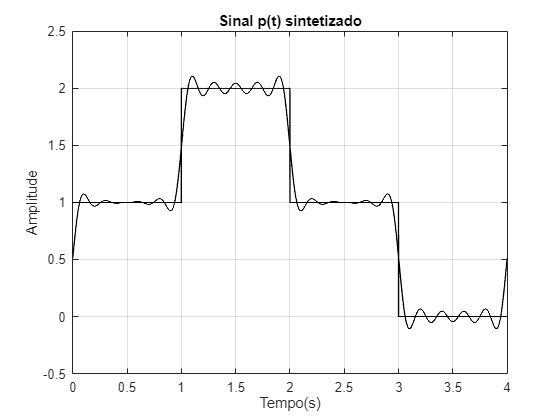

plot(t2, pulse1+pulse2+pulse3, 'LineWidth',1,'Color','k'); hold on;    %%% Gráfico das onda pulsada
plot(t2, aux, 'LineWidth',1,'Color','k', 'LineStyle','-')              %%% Gráfico do sinal sintetizado
hold off;

title('Sinal p(t) sintetizado')                                        %%% Título do gráfico
xlabel('Tempo(s)')                                                     %%% Título do eixo x
ylabel('Amplitude')                                                    %%% Título do eixo y
grid;                                                                  %%% Exibir com o quadriculado 

## Exercício 5

Sim. É perceptível que o sinal $g(t)$ é uma combinação dos pulsos $f(t)$ com ajustes de amplitude e deslocamento. $g(t)$ pode ser quebrado na soma de 3 pulsos $f(t)$, onde os ajustes de deslocamento e de amplitude transformam ela em uma função contínua que dependa apenas do sinal de $f(t)$. O primeiro pulso de g(t) pode ser expresso como: $p\left(t-\frac{1}{2}\right)$, o segundo como: $2p\left(t-\frac{3}{2}\right)$ e o terceito como: $p\left(t-\frac{5}{2}\right)$. Assim, unindo os três pulsos temos que:


$$g\left(t\right)=p\left(t-0\ldotp 5\right)+p\left(t-1\ldotp 5\right)+p\left(t-2\ldotp 5\right)$$
